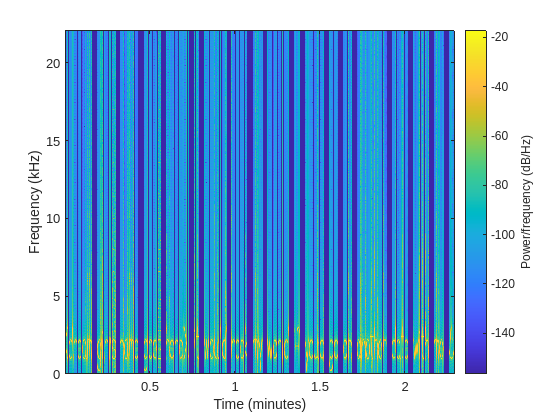

%this function is used to create a continuous time spectrogram using
%matlab's built in pwelch, spectrogram, and imagesc

%sets the basic parameters of the sample rate and frame size, etc
SampleRate = 48000;
bitPrecision = 24;
seconds = 3;



%sets up the audioReader object
recorder = audiorecorder(SampleRate, bitPrecision, NumChannels);

%records in the input audio data
%recordblocking(recorder, seconds);
%inputData = getaudiodata(recorder);


%%saves the audio as a wav file
%audiowrite('sometimes_y_sound.wav', inputData, SampleRate);


%reads in the wav file from audio cubed
[y, Fs] = audioread(['GeekCubed.wav']);


%gets the spectrogram of the wav file
spectrogram(y, 10000, 500, 4096, Fs,'yaxis');